% Clear Workspace
clear all
clc

% Read STL File
% stl1 = stlread("Test Objects\Box.stl");
% stl1 = stlread("Test Objects\cubeWithHole.STL");
% stl1 = stlread("Test Objects\cylinder.STL");
% stl1 = stlread("Test Objects\Case.STL");
% stl1 = stlread("Test Objects\AdaptiveSlicingFigureA.stl");
stl1 = importSTL("Test Objects\weirdShape.STL");

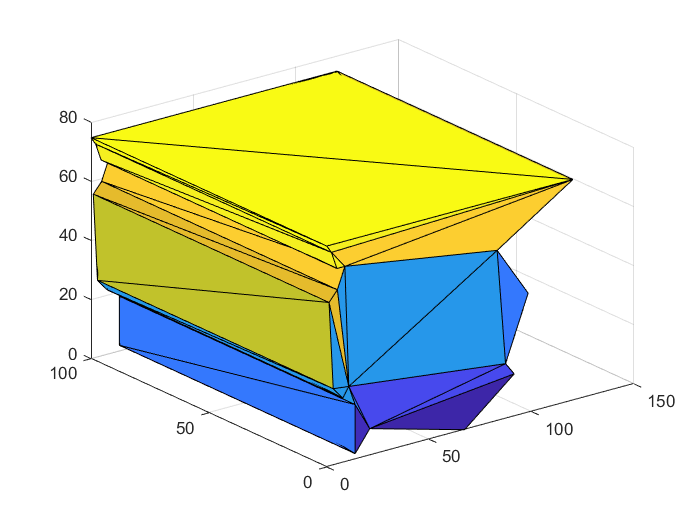

% stl1 = stlread("Test Objects\keys.STL"
% stl1 = stlread("Test Objects\Witcher_towel_hook.stl");

% Rotated stl
% rotatedSTL = stlRotate(stl1);
% rotatedSGO = FlatUniformSliceGenerator(rotatedSTL,10);
% rotatedSGO.generateSlices();
% op2 = rotatedSGO.getSlicePath();

% stl1 = stlTransform(stl1, 90, 0, 0, 1, 0, 0, 0, 100);
trisurf(stl1)
hold on


% Create SliceGeneratorObject
sliceHeight = 0.2;
%sliceGen = FlatUniformSliceGenerator(stl1, sliceHeight)
sliceGen = FlatAdaptiveSliceGenerator(stl1, sliceHeight)

sliceGen =   FlatAdaptiveSliceGenerator with properties:

                       layerProfiles: [4×5 double]
    adaptiveSlicerElementInformation: [0×3 double]
                                 obj: []
                    connectivityList: [68×3 double]
                       numOfElements: 68
                              points: [204×3 double]
                      sliceThickness: 0.2000
                           slicePath: []
                           slicerTol: 1.0000e-05



% Manual Slice for Debugging - Comment out if not used.
figure(2);
test = sliceGen.slicePathLayer(5)

test =    16.9202   43.2600    5.0000    1.0000
   16.9202  100.0000    5.0000    1.0000
   13.8429  100.0000    5.0000    1.0000
   13.8429   81.4702    5.0000    1.0000
   13.8429         0    5.0000    1.0000
   16.9202         0    5.0000    1.0000
   16.9202   43.2600    5.0000    1.0000
   16.9202   43.2600    5.0000    1.0000
   75.7291   34.8297    5.0000    2.0000
   75.7291         0    5.0000    2.0000


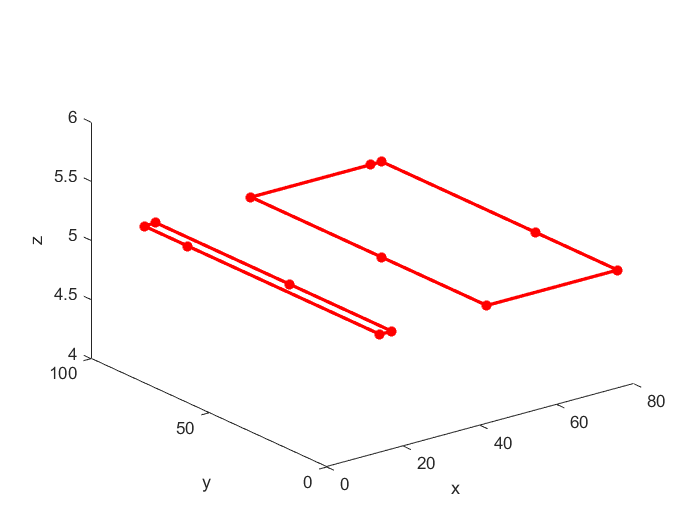

for j = 1:max(test(:,4))

    pathPlotPoints = test(test(:,4) == j,:);
    plot3(pathPlotPoints(:,1), pathPlotPoints(:,2), pathPlotPoints(:,3),'-r*','LineWidth',2);
    hold on

end
xlabel('x');
ylabel('y');
zlabel('z');
view(3);


% Generate Full Slice Path
figure(3);
op = sliceGen.getSlicePath()

op =    67.2916  100.0000         0    1.0000
   67.2916   -0.0000         0    1.0000
   67.2916  100.0000         0    1.0000
   67.4604  100.0000    0.1000    1.0000
   67.3992  100.0000    0.1000    1.0000
   66.7789  100.0000    0.1000    1.0000
   66.7789   98.8934    0.1000    1.0000
   66.7789   -0.0000    0.1000    1.0000
   67.4604         0    0.1000    1.0000
   67.4604    0.6966    0.1000    1.0000


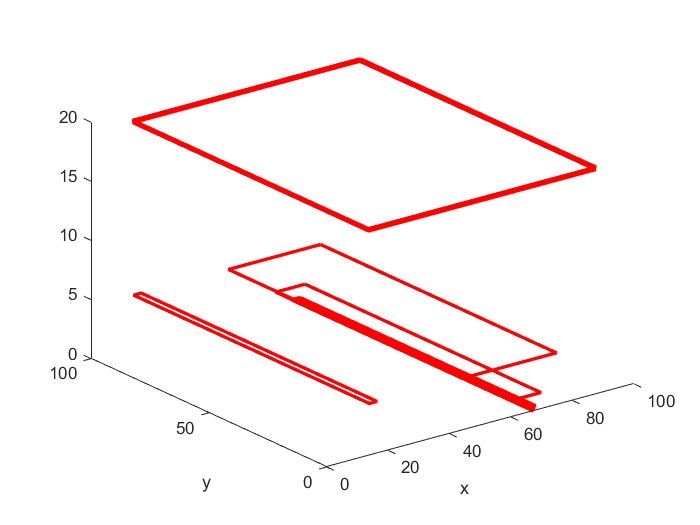

for i = 0:sliceHeight:double(max(op(:,3)))
    
    zPlotPoints = op(op(:,3) == i,:);
    for j = 1:max(zPlotPoints(:,4))
        pathPlotPoints = zPlotPoints(zPlotPoints(:,4) == j,:);
        plot3(pathPlotPoints(:,1), pathPlotPoints(:,2), pathPlotPoints(:,3),'-r','LineWidth',2);
        hold on
    end

end
xlabel('x')
ylabel('y')
view(3);


% Testing of Infill Generator
pathWithInfill = FlatSliceInfillGenerator(op, 20);